R = rot2(0.2); %Angle is specified in radians
%syms theta
% R = rot2(theta)

rot2 has an homogeneuous equivalent trot2

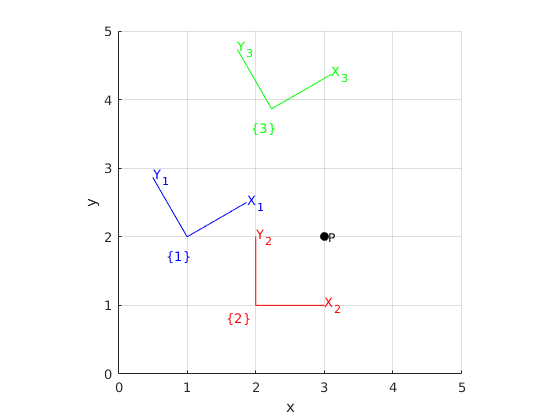

T1 = transl2(1,2) * trot2(30, 'deg'); %Translation and Rotation

plotvol([0 5 0 5]);
trplot2(T1, 'frame', '1', 'color', 'b');

T2 = transl2(2,1);
trplot2(T2, 'frame', '2', 'color', 'r');
T3 = T1 * T2;
trplot2(T3, 'frame', '3', 'color', 'g');

P = [3; 2];
plot_point(P, 'label', 'P', 'solid', 'ko');

P1 = inv(T1) * [P;1];

Centers of Rotation

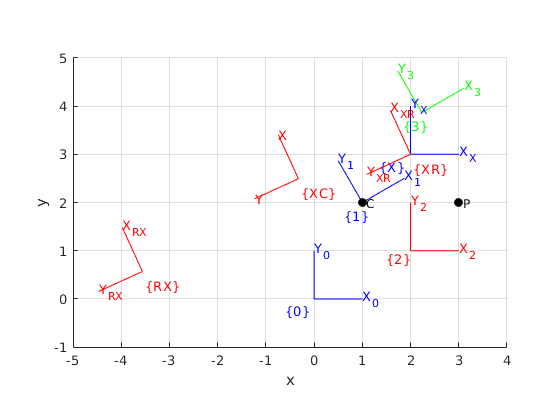

plotvol([-5 4 -1 5]);
T0 = eye(3,3);
trplot2(T0, 'frame', '0');
X = transl2(2,3);
trplot2(X, 'frame', 'X');
R = trot2(2);

trplot2(R*X, 'frame', 'RX', 'color', 'r');
trplot2(X*R, 'frame', 'XR', 'color', 'r');

C = [1 2]';
plot_point(C, 'label', 'C', 'solid', 'ko');
RC = transl2(C) * R * transl2(-C);
trplot2(RC * X, 'framelabel', 'XC', 'color', 'r');

C = [1 2]';
tw = Twist('R', C);
disp( tw.T(2) );

   -0.4161   -0.9093    3.2347
    0.9093   -0.4161    1.9230
         0         0    1.0000



disp( tw.pole' );

     1     2




tw = Twist('T', [1 1]);
tw.T(sqrt(2));

disp("===")

===


T = transl2(2,3) * trot2(0.5);
disp(T);

    0.8776   -0.4794    2.0000
    0.4794    0.8776    3.0000
         0         0    1.0000



tw = Twist(T);
disp(tw)

  Twist with properties:

    v: [2×1 double]
    w: 0.5000



disp(tw.T)

    0.8776   -0.4794    2.0000
    0.4794    0.8776    3.0000
         0         0    1.0000



Rotation in 3-Dimensions using orthonormal rotation matrices

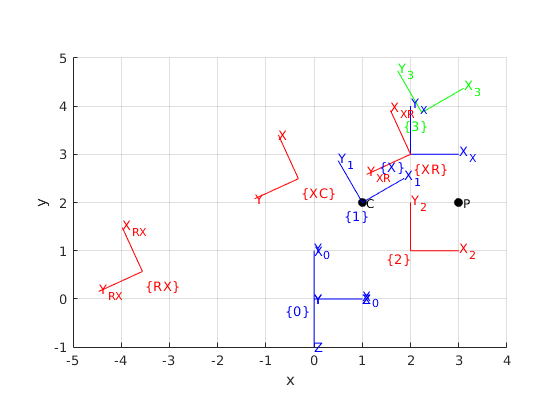

R = rotx(pi/2);
% trplot(R);
tranimate(R);% tranimate(R, '3d'); For those with 3D glasses
R = rotx(pi/2) * roty(pi/2);
tranimate(R);


% Rotation using 3-angle representation
R = rotz(0.1) * roty(0.2) * rotz(0.3);
R = eul2r(0.1, 0.2, 0.3); %convenient method
angles = tr2eul(R); %Inverse, returns the euler angles corresponds to a given rotation

% Rotations using Roll, Pitch and Yaw
R = rpy2r(0.1, 0.2, 0.3); % Default is ZYX axis
rpy = tr2rpy(R); % Inverse

**Matrix Exponentials**

Rotation about an x-axis

R = rotx(0.3)

R =     1.0000         0         0
         0    0.9553   -0.2955
         0    0.2955    0.9553



%Computing its logarithm
S = logm(R)

S =          0         0         0
         0         0   -0.3000
         0    0.3000         0


**Twists**

tw = Twist('T', [0 1 0])

 
tw = 
( 0  1  0; 0  0  0 )


tw.T(1)

ans =      1     0     0     0
     0     1     0     1
     0     0     1     0
     0     0     0     1


tw.T(2)

ans =      1     0     0     0
     0     1     0     2
     0     0     1     0
     0     0     0     1



X = transl(3, 4, -4) % Coordinate frame X

X =      1     0     0     3
     0     1     0     4
     0     0     1    -4
     0     0     0     1


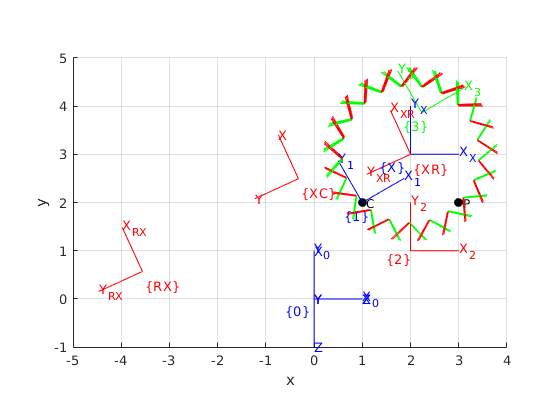

angles = [0:0.3:15];

screw = Twist('R', [0 0 1], [2 3 2], 0.5);
tranimate( @(theta) screw.T(theta) * X, angles, 'length', 0.5, 'retain','rgb','notext');